(30-45 minutes)

To do:

- finish descriptions; link doc where approrpiate

- decide whether to include content from this example about multiple gain or phase crossings: [https://www.mathworks.com/help/control/ug/assessing-gain-and-phase-margins.html](https://www.mathworks.com/help/control/ug/assessing-gain-and-phase-margins.html) 

- PID Tuner app section: pick parameters (margins, overshoot, etc.) to "beat" by tuning in the app

Question for dev - right-click characteristics in live editor figures/web figures? It works in figures plotted from command line in MATLAB online

# Step 1: Basic Control Design Concepts

In this section, we will ...

## Build a feedback loop

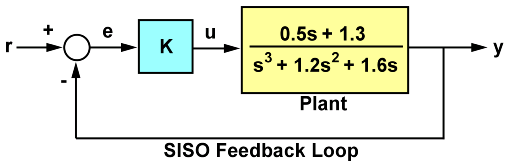

You can build components of a feedback loop in MATLAB using LTI objects. Use a transfer function object to create the plant for the loop shown above:

G = tf([.5 1.3],[1 1.2  1.6 0])

G =
 
       0.5 s + 1.3
  ---------------------
  s^3 + 1.2 s^2 + 1.6 s
 
Continuous-time transfer function.



The controller in the diagram above has a gain of "K", but doesn't give us a value for K. We can plot our plant's root locus to estimate the range of K values for which the loop would be stable:

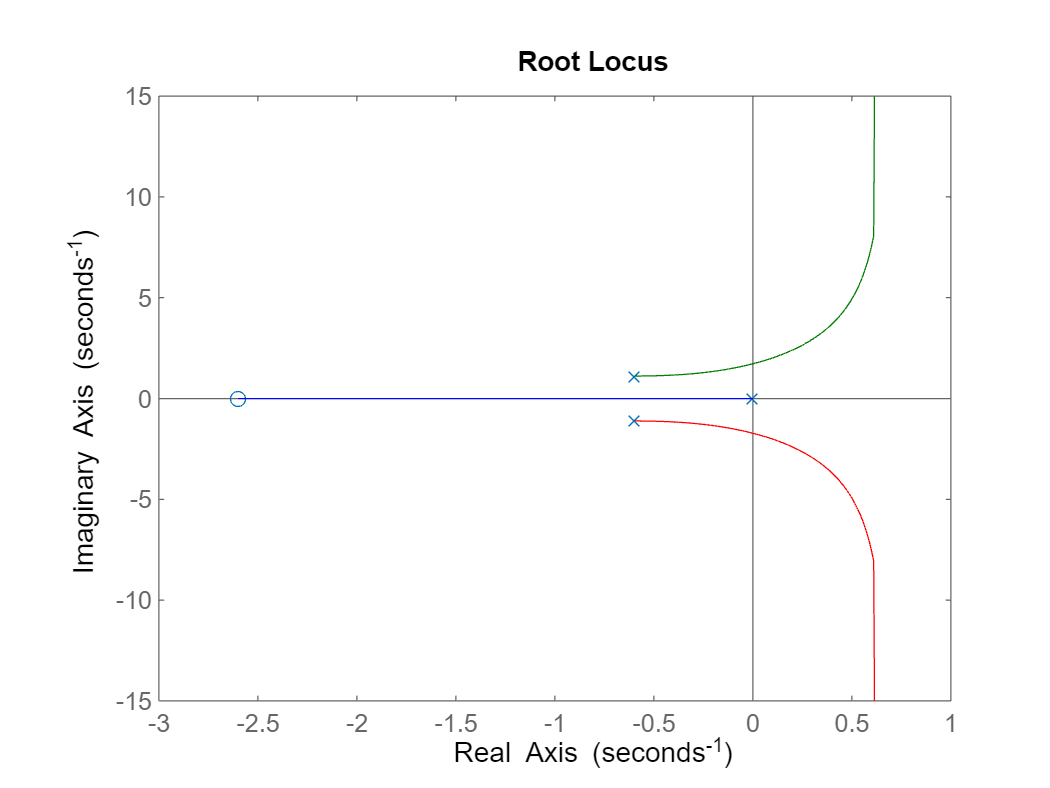

rlocus(G)

From the plot, we can see the feedback loop is stable for 0 < K < 2.7. Use a transfer function object to create the controller, using a K value to 1 to start.

C = tf(1,1)

C =
 
  1
 
Static gain.



Connect the LTI objects into a feedback loop using the feedback function.

T = feedback(C*G,1)

T =
 
          0.5 s + 1.3
  ---------------------------
  s^3 + 1.2 s^2 + 2.1 s + 1.3
 
Continuous-time transfer function.



## Check stability

There are many ways to determine if a control system is stable...

### Poles

pole(T)

ans =   -0.2305 + 1.3062i
  -0.2305 - 1.3062i
  -0.7389 + 0.0000i


All the poles have negative real parts, therefore the feedback loop for K = 1 is stable.

### Gain and Phase Margins

Changes in the loop gain are only one aspect of robust stability. In general, imperfect plant modeling means that both gain and phase are not known exactly. Because modeling errors are most damaging near the gain crossover frequency (frequency where open-loop gain is 0dB), it also matters how much phase variation can be tolerated at this frequency.

The phase margin measures how much phase variation is needed at the gain crossover frequency to lose stability. Similarly, the gain margin measures what relative gain variation is needed at the gain crossover frequency to lose stability. Together, these two numbers give an estimate of the "safety margin" for closed-loop stability. The smaller the stability margins, the more fragile stability is.

Create a bode plot:

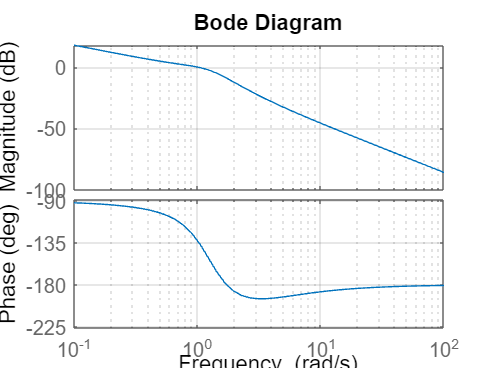

bode(C*G), grid

Calculate gain and phase margins:

[Gm,Pm] = margin(C*G);
GmdB = 20*log10(Gm)

GmdB = 8.7641

Pm

Pm = 44.6703

You can also get the gain and phase margins directly from the bode plot. Run `bode(C*G), grid` from the command line. Right-click on the plot and select "Characteristics -> Minimum Stability Margins". Then, click on the blue dot markers to see the margins and other values.

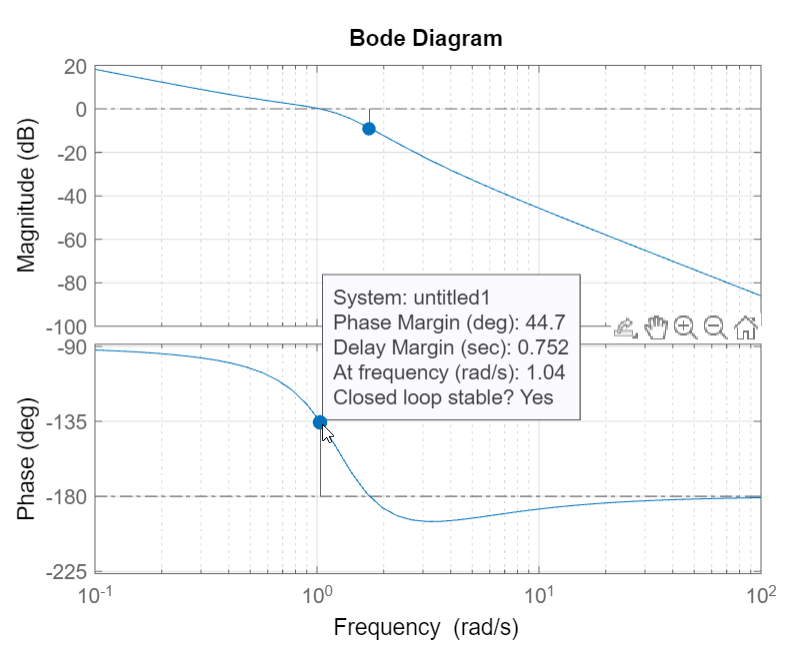

### Step Response

We can also look at a closed-loop step response. When K = 1, there is ~20% overshoot and some oscillations.

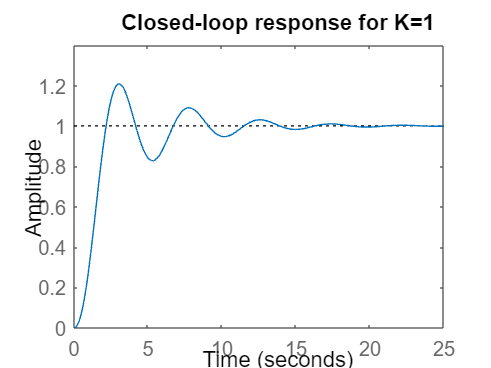

step(T), title('Closed-loop response for K=1')

Similarly to the bode plot, you can also get response characteristics directly from the step response plot. Run `step(T)` from the command line. Right click on the plot and select "Characteristics -> Peak Response". Then, click on the blue dot marker to see the values.

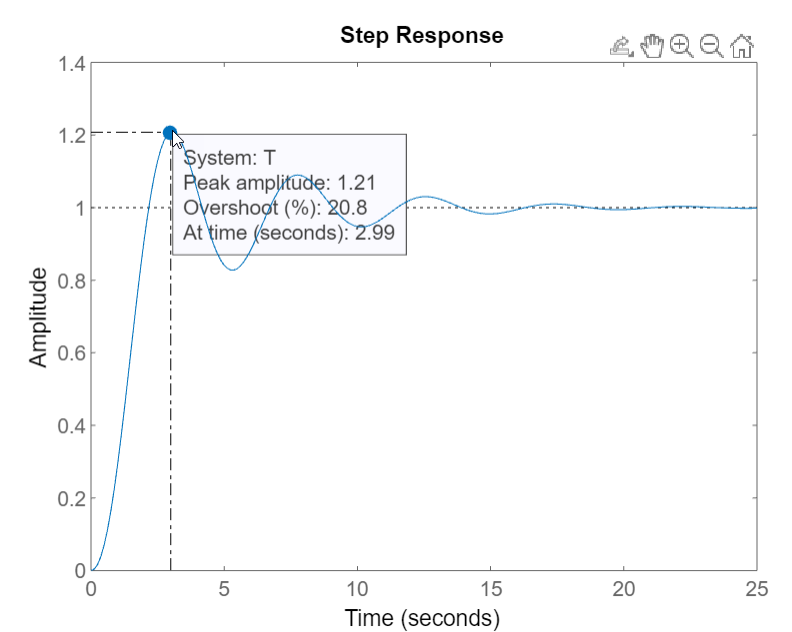

## Check stability for different controller gains

### Change the controller gain

From the root locus plot, we estimated the feedback loop would be stable for 0 < K < 2.7. Let's change the controller transfer function to use a gain of K = 2 instead of K = 1.

C = tf(2,1)

C =
 
  2
 
Static gain.



Connect the LTI objects into a feedback loop using the feedback function.

T = feedback(C*G,1)

T =
 
            s + 2.6
  ---------------------------
  s^3 + 1.2 s^2 + 2.6 s + 2.6
 
Continuous-time transfer function.



### Poles

Based on the root locus plot, we expect a gain of 2 to lead to a stable system. Let's check for stability by looking at the loop's poles: 

pole(T)

ans =   -0.0698 + 1.5643i
  -0.0698 - 1.5643i
  -1.0604 + 0.0000i


As expected, all the poles have negative real parts - the feedback loop for k = 2 is stable.

### Gain and Phase Margins

Create a bode plot:

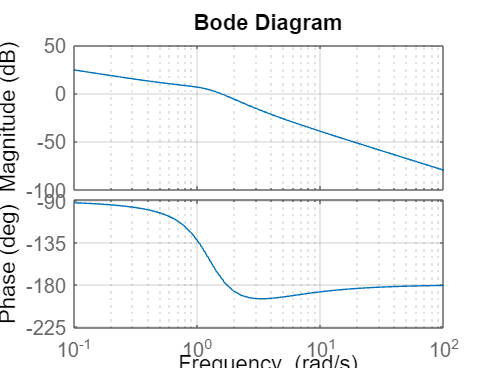

bode(C*G), grid

Calculate gain and phase margins:

[Gm,Pm] = margin(C*G);
GmdB = 20*log10(Gm)

GmdB = 2.7435

Pm

Pm = 8.6328

The stability margins have been reduced.

### Step Response

We can also look at a closed-loop step response. When k = 2, there is poorly damped oscillations, which is a sign of near instability.

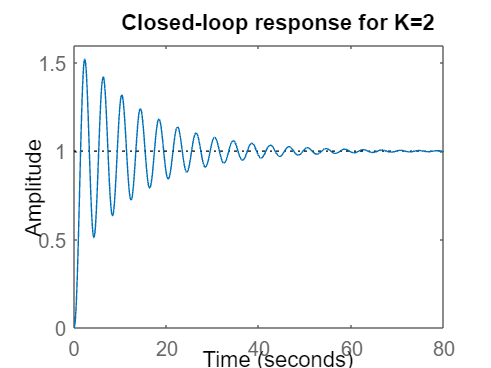

step(T), title('Closed-loop response for K=2')

## Multiple Gain or Phase Crossings (???)

https://www.mathworks.com/help/control/ug/assessing-gain-and-phase-margins.html

## Explore Controls Live Tasks & Apps

Tasks and apps help you... (interactive, etc.)

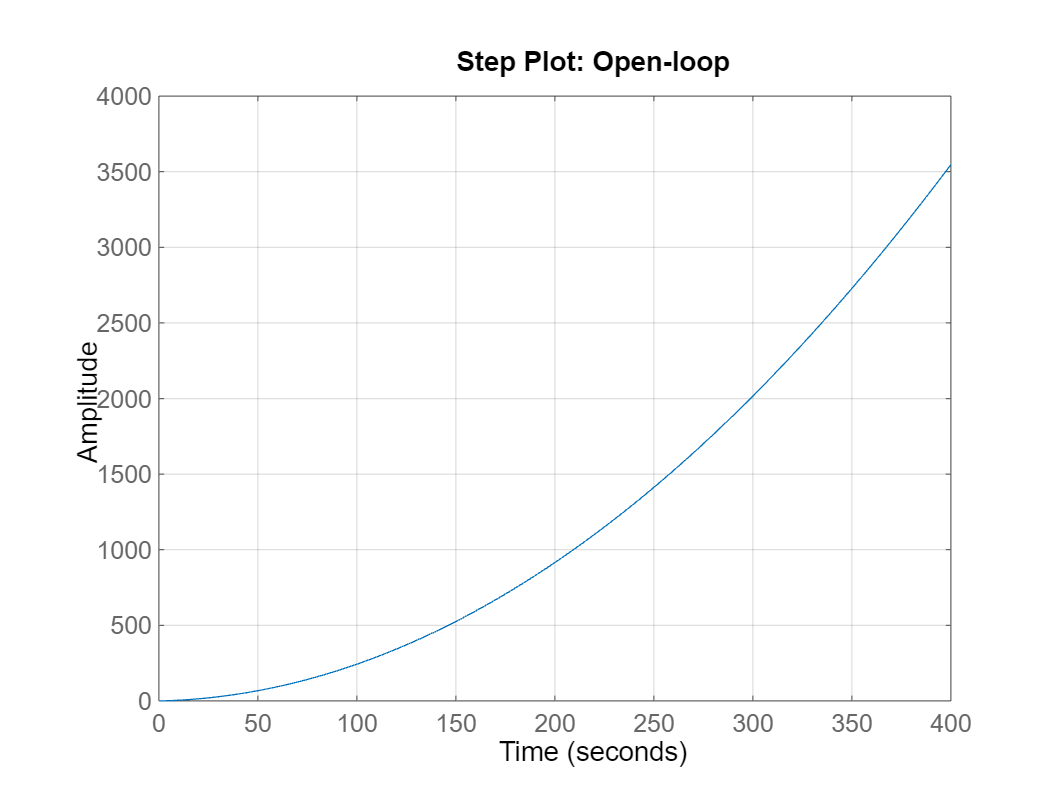

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/5.74967;

% PID tuning algorithm for linear plant model
[C2,pidInfo] = pidtune(G,'PI',wc);

% Clear Temporary Variables
clear wc

% Get desired loop response
Response = getPIDLoopResponse(C2,G,'open-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Open-loop')
grid on


% Display system response characteristics
Response = getPIDLoopResponse(C2,G,'closed-loop');
disp(stepinfo(Response))

         RiseTime: 2.7596
    TransientTime: 22.9694
     SettlingTime: 22.9694
      SettlingMin: 0.9218
      SettlingMax: 1.2176
        Overshoot: 21.7618
       Undershoot: 0
             Peak: 1.2176
         PeakTime: 9.7126




% Clear Temporary Variables
clear Response

Let's use the PID Tuner app to see if we can find a better controller for our plant "G". Open the PID Tuner app: 

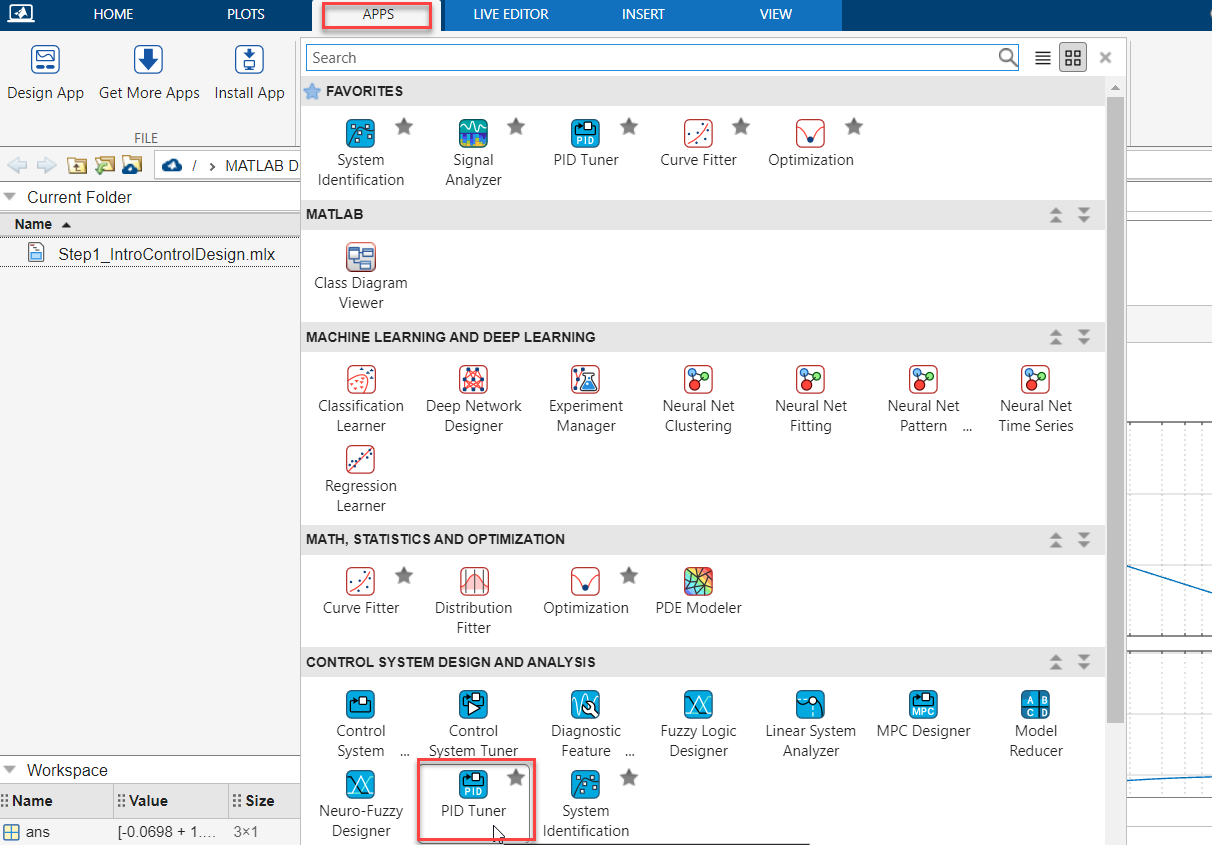

Import "G" as the plant:

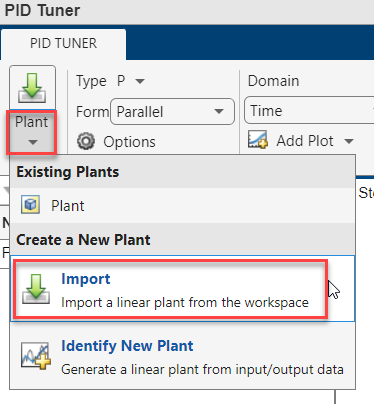

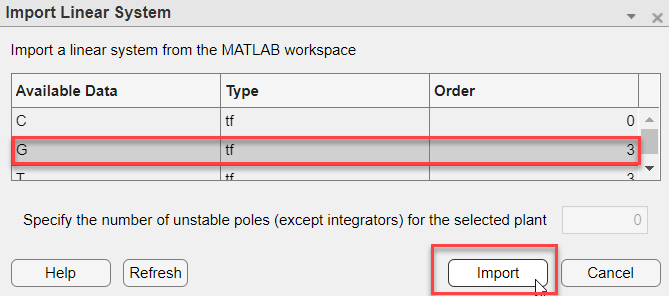

Keep the controller type as "P". The tool will automatically suggest a Kp gain that balances response time and transient behavior. Click "Show Parameters" to see the system's *<parameters we want to measure against - overshoot, rise time, etc.> *

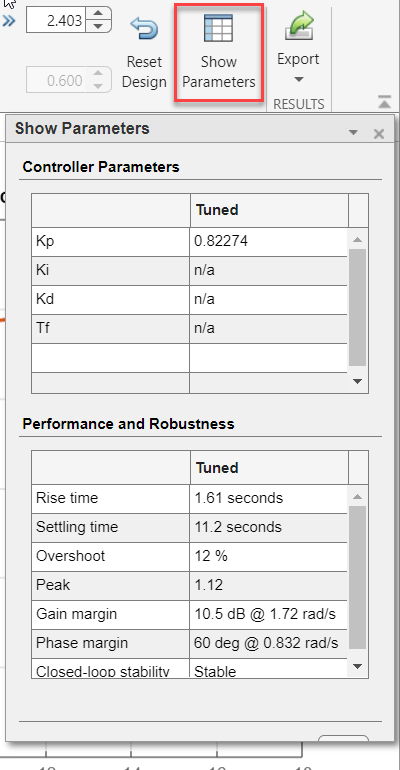

Use the slider to further tune the Kp gain. Can you find a value of Kp for *<certain overshoot/rise time/settling time requirement?>*.

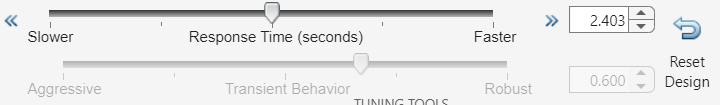

**Bonus activities:**

Try switching the tuning domain to "frequency" and add a bode plot to visualize the response to different Kp gains.

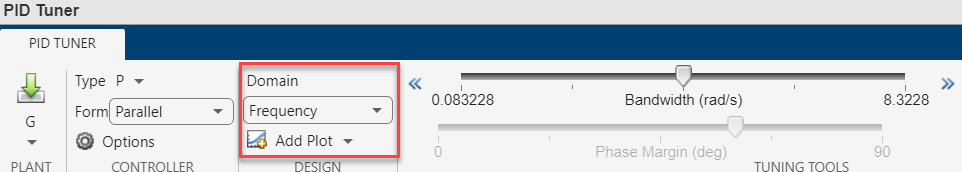

Try a different controller type. Can you get better results with a different controller type?